`load  'pub_dataset2.mat'`

`tic`

`n = numel(data_tr(:,55));`

`rng(1) % For reproducibility`

`idx = randsample(n,n);`

`X = data_tr(idx,1:54);`

`Y = data_tr(idx,55);`

`% Normalize the data`

`X = (X - min(X)) ./ (max(X) - min(X));`

`initobs = 100; % Increase the initial batch size`

`Mdl = incrementalClassificationECOC('MaxNumClasses',2,'MetricsWindowSize',1000,...`

`    'Metrics','classiferror','MetricsWarmupPeriod',initobs);`

`Mdl = fit(Mdl,X(1:initobs,:),Y(1:initobs));`

`haveTrainedAllClasses = numel(unique(Y(1:initobs))) == 2`

`% Preallocation`

`numObsPerChunk = 50;`

`nchunk = floor((n - initobs)/numObsPerChunk);`

`mu21 = zeros(nchunk,1);`

`ce = array2table(nan(nchunk,2),'VariableNames',["Cumulative" "Window"]);`

`trained = false(nchunk,1);`

`% Incremental fitting`

`for j = 1:nchunk`

`    ibegin = min(n,numObsPerChunk*(j-1) + 1 + initobs);`

`    iend   = min(n,numObsPerChunk*j + initobs);`

`    idx = ibegin:iend;`

`    Mdl = updateMetrics(Mdl,X(idx,:),Y(idx));`

`    ce(j,:) = Mdl.Metrics("ClassificationError",:);  % Update this line`

`    if ce{j,"Window"} > 0.005`

`        Mdl = fit(Mdl,X(idx,:),Y(idx));`

`        trained(j) = true;`

`    end`

`end`

% t = tiledlayout(2,1);
% nexttile
% plot(mu21)
% hold on
% plot(find(trained),mu21(trained),'r.')
% ylabel('\mu_{21}')
% legend('\mu_{21}','Training occurs','Location','best')
% hold off
% nexttile
% plot(ce.Variables)
% ylabel('Misclassification Error Rate')
% legend(ce.Properties.VariableNames,'Location','best')
% xlabel(t,'Iteration')

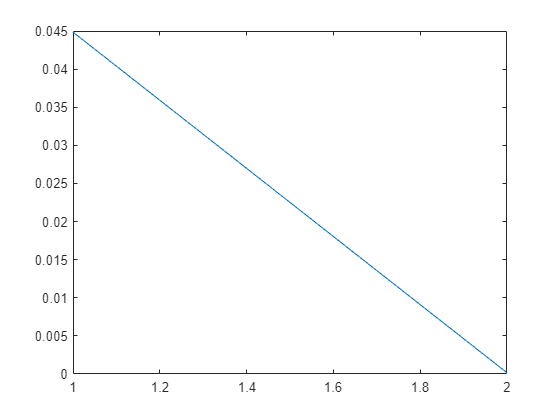

% Add this code after the incremental fitting loop:
t = tiledlayout(1,1);
nexttile
plot(ce(:,:))
hold on

disp(size(trained));

    30     1



disp(size(ce));

     1     2




plot(find(trained), ce(trained, 2), 'r.', 'MarkerSize', 10)

The logical indices in position 1 contain a true value outside of the array bounds.


ylabel('Misclassification Error Rate')
legend(["Cumulative", "Window", "Training occurs"], 'Location', 'best')
xlabel(t, 'Iteration')
hold off

 Mdl = updateMetrics(Mdl,data_te(:, 1:54),data_te(:,55));
    ce = Mdl.Metrics{"ClassificationError",:}
output_test = predict(Mdl,data_te(:, 1:54));
accuracy = sum(output_test == data_te(:,55))/numel(data_te(:,55))
precision = sum(output_test & data_te(:,55)) / sum(output_test)
recall = sum(output_test & data_te(:,55)) / sum(data_te(:,55))
F1_score = 2 * (precision * recall) / (precision + recall)
waktu = toc